# XFOIL Proof

syms x
v = 2.602e-5;
Uinf = 178.816; %m/s
cf_turb = @(x) 0.0592*v^0.2/(Uinf*x)^0.2;
Cdwing = vpa((2/3.5)*int(cf_turb,x,0,3.5),4)

$$Cdwing = 0.004943$$

# Compressability Proof 

clc
clear
 
M = 0.3:0.1:0.8; 
m = mfoil('naca','4412', 'npanel',199);

%incompressable flow over mach with PrandtlG scaling
for i = 1:1:6
    %set parameters 
    m.setoper('alpha',2,'Re',10^6)
    % run the solver, plot the results 
    m.solve;
    Cd_prandtlG(i) = m.post.cd/sqrt(1-M(i)^2);
end 


 <<< Solving inviscid problem >>> 
  alpha=2.00deg, cl=0.751563, cm=-0.114613, cdpi=-0.001133, cd=0.000000, cdf=0.000000, cdp=0.000000

 <<< Initializing the boundary layer >>> 
  transition on upper side at x=0.46414

 <<< Beginning coupled solver iterations >>> 
  transition on upper side at x=0.46414
  alpha=2.00deg, cl=0.721973, cm=-0.105828, cdpi=-0.004533, cd=0.009401, cdf=0.004785, cdp=0.004616

Newton iteration 1, Rnorm = 1.03146e-01
  transition on upper side at x=0.47053
  alpha=2.00deg, cl=0.731734, cm=-0.109013, cdpi=-0.003067, cd=0.008960, cdf=0.004793, cdp=0.004166

Newton iteration 2, Rnorm = 3.01910e-01
  transition on upper side at x=0.47500
  alpha=2.00deg, cl=0.712483, cm=-0.105237, cdpi=-0.002297, cd=0.008496, cdf=0.004942, cdp=0.003553

Newton iteration 3, Rnorm = 5.46266e-01
  transition on upper side at x=0.47775
  alpha=2.00deg, cl=0.656509, cm=-0.092528, cdpi=-0.002247, cd=0.007436, cdf=0.004794, cdp=0.002643

Newton iteration 4, Rnorm = 5.26357e-01
  transiti

display(Cd_prandtlG)

Cd_prandtlG =     0.0066    0.0068    0.0072    0.0078    0.0088    0.0104




%compressable flow over mach
for i = 1:1:6
    %set parameters 
    m.setoper('alpha',2, 'Re',10^6, 'Ma',M(i));
    % run the solver, plot the results 
    m.solve;
    Cd_Mfoil(i) = m.post.cd;
end 


 <<< Solving inviscid problem >>> 
  alpha=2.00deg, cl=0.799348, cm=-0.120765, cdpi=-0.002290, cd=0.000000, cdf=0.000000, cdp=0.000000

 <<< Initializing the boundary layer >>> 


  transition on lower side at x=0.99797
  transition on upper side at x=0.45882

 <<< Beginning coupled solver iterations >>> 
  transition on lower side at x=0.99877
  transition on upper side at x=0.45882
  alpha=2.00deg, cl=0.794309, cm=-0.118861, cdpi=-0.002525, cd=0.005907, cdf=0.005123, cdp=0.000784

Newton iteration 1, Rnorm = 1.40226e+00
  transition on upper side at x=0.46575
  alpha=2.00deg, cl=0.789993, cm=-0.119379, cdpi=-0.000928, cd=0.006808, cdf=0.005002, cdp=0.001806

Newton iteration 2, Rnorm = 8.82692e-01
  transition on lower side at x=0.98384
  transition on upper side at x=0.46663
  alpha=2.00deg, cl=0.851258, cm=-0.132974, cdpi=-0.001002, cd=0.006935, cdf=0.004959, cdp=0.001977

Newton iteration 3, Rnorm = 6.96537e-01
  transition on lower side at x=0.99723
  transition on upper side at x=0.47122
  alpha=2.00deg, cl=0.800214, cm=-0.121873, cdpi=-0.000400, cd=0.006688, cdf=0.004643, cdp=0.002045

Newton iteration 4, Rnorm = 7.11964e-01
  transition on upper side at

display(Cd_Mfoil)

Cd_Mfoil =     0.0065    0.0068    0.0072    0.0078    0.0091    0.0139


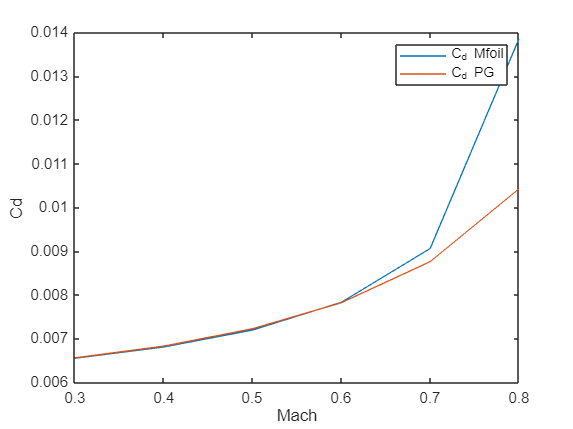




figure 
plot(M,Cd_Mfoil)
hold on 
plot(M,Cd_prandtlG)
hold off
ylabel('Cd')
xlabel('Mach')
axis([0.3 0.8 0.006 0.03])
legend("C_d Mfoil","C_d PG")